# Lab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to 

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$ axes of the frame {B} is 30 deg counterclockwise.

##  1.1 Which are the coordinates of the origin of A seen from B?

% We make the Rotation matrix
% We know that the angle of rotation is 60 deg because it's the one that
% meets the statement's conditions
bRa = [cosd(60),-sind(60);
       sind(60),cosd(60)];
   
 
 %We know that p_B = bRa * p_A' + bdB_A;
 % So we isolate the distance
 
 bdB_A = p_B - (bRa * p_A);
%We know that the origin of B as seen from b is [0,0], so the vector
%distance to a certain point taking b as an origin is the same coordinate
%of that point as seen from b.
%In this case, the origin of A
BoA = bdB_A

BoA =    -0.5359
   -4.0981


##  1.2 Which are the coordinates of the origin of B seen from A?

%We calculate the rotation matrix
% We know that the Rotation that goes from the frame B to A is the inverse
% of the Rotation Matrix that goes from the frame A to B. Since is a
% Rotation Matrix, the inverse equals the transposed.

 aRb = bRa';

% We know that p_A = aRb * p_B' + adA_B;
 % So we isolate the distance
 adA_B = p_A - (aRb * p_B);
 
 % We can also rotate the vector distance that we previously calculated
 adA_B2 = aRb*-bdB_A 

adA_B2 =     3.8170
    1.5849


%The same we described before, apllies to this; but in this case, the frame
%A is the origin.
aoB = adA_B2

aoB =     3.8170
    1.5849


##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';

%Since we know all the variables, we just apply the previously applicated
%formula

q_A = aRb * q_B + adA_B

q_A =     6.1830
   -0.5131


# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}  (which imply $^B v = R(\psi, \theta, \phi)\, ^Av$)

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5];

                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.

Bv = bAc * Cv;

## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and comment why do you think it is well implemented.

rotVbtqTest = rotVbtq(BoC,q);

%We think the function is well implemented because we have converted the
%vector to a quaternion, then normalized the quaternion and put them in a
%visible way using multiple variables for the same quaterion.
% Then we apllied correctly the rotation developing the quaternion multiplication
% formula by using QL(q)*QR(qº)*v.

##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

aRb = transpose(eAngles2rotM(25,145,30));
aAb = [aRb, AoB  ; 0 0 0 1];

bRc = quaternion2rotM(q);
bAc = [bRc BoC,  ; 0 0 0 1];

aAc = aAb * bAc;

## 2.3 The vectors v1_C and v2_C form a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

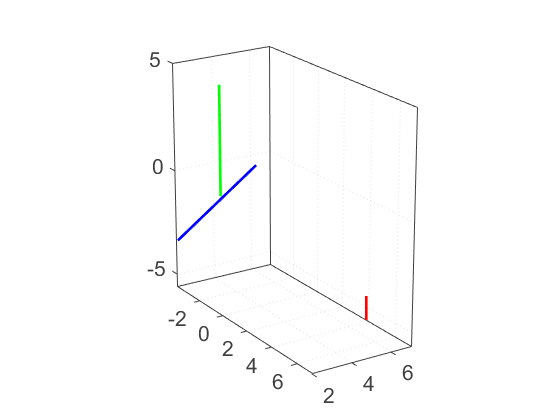

v1_Ch = [v1_C; 1];

v1_Bh = bAc * v1_Ch;
v1_Ah = aAc * v1_Ch;

v2_Ch = [v2_C; 1];
v2_Bh = bAc * v2_Ch;
v2_Ah = aAc * v2_Ch;

axes1 = axes('Parent',figure,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'ZColor',[0.25,0.25,0.25],...
    'Projection','perspective',...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes1,'on');
view(axes1,[57 20]);
hold(axes1,'all');


%Plot the triad
plot3([v2_Ah(1);v1_Ah(1)],[v2_Ah(2);v1_Ah(2)],[v2_Ah(3);v1_Ah(3)],'Color',[1,0,0],'LineWidth',2)
plot3([v2_Ch(1);v1_Ch(1)],[v2_Ch(2);v1_Ch(2)],[v2_Ch(3);v1_Ch(3)],'Color',[0,1,0],'LineWidth',2)
plot3([v2_Bh(1);v1_Bh(1)],[v2_Bh(2);v1_Bh(2)],[v2_Bh(3);v1_Bh(3)],'Color',[0,0,1],'LineWidth',2)

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

wc = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

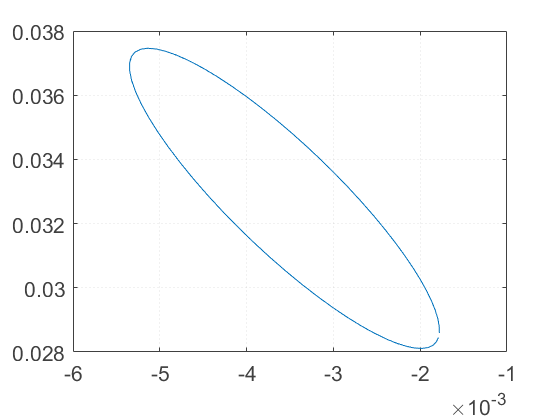

cRw= transpose(eAngles2rotM(0,90,-20));
cAw= [cRw wc ; 0 0 0 1];
f=1/34;

axes2 = axes('Parent',figure,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'FontSize',16);
box(axes2,'on');
hold(axes2,'all');

cpP = cameraproj(cAw, f, A);
plot(cpP(1,:),cpP(2,:));

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

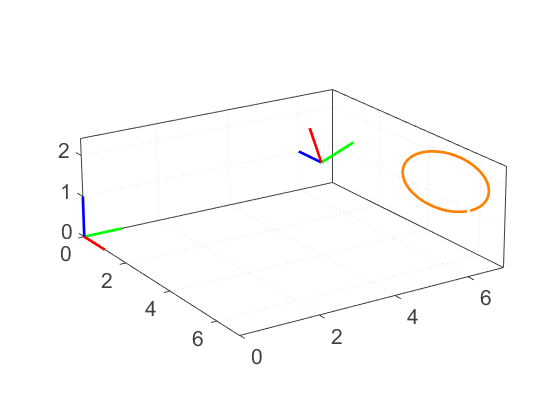

axes3 = axes('Parent',figure,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'ZColor',[0.25,0.25,0.25],...
    'Projection','perspective',...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes3,'on');
view(axes3,[57 20]);
hold(axes3,'all');

%Plot the world triad--------------------------------------
%Vectors for an world triad-----
w1 = [1,0,0]';
w2 = [0,1,0]';
w3 = [0,0,1]';

%Plot the triad-------
plot3([0;w1(1)],[0;w1(2)],[0;w1(3)],'Color',[1,0,0],'LineWidth',2)
plot3([0;w2(1)],[0;w2(2)],[0;w2(3)],'Color',[0,1,0],'LineWidth',2)
plot3([0;w3(1)],[0;w3(2)],[0;w3(3)],'Color',[0,0,1],'LineWidth',2)

%Camera triad----------------------------------------------
%Calculate the triad----
c1 = cAw *[w1; 1] ;
c2 = cAw * [w2;1];
c3 = cAw * [w3;1];

%Plot th cam triad-------
plot3([wc(1);c1(1)],[wc(2);c1(2)],[wc(3);c1(3)],'Color',[1,0,0],'LineWidth',2)
plot3([wc(1);c2(1)],[wc(2);c2(2)],[wc(3);c2(3)],'Color',[0,1,0],'LineWidth',2)
plot3([wc(1);c3(1)],[wc(2);c3(2)],[wc(3);c3(3)],'Color',[0,0,1],'LineWidth',2)

%Plot the circle----------
plot3(A(1,:),A(2,:),A(3,:),'Color',[1,0.5,0],'LineWidth',2)

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A

A =     0.9115    3.7207    1.9659    2.6663
    1.9397    2.8794    1.0000    3.8191
    3.3304    4.4372    3.2588    4.5087


From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

wc = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

wseg_1 = [A(:,2) - A(:,1) ];
wseg_2 = [A(:,4) - A(:,3) ];

minAngle = acosd(dot(wseg_1, wseg_2)/(norm(wseg_1) * norm(wseg_2)) );

## 4.2 The angle that both segments forms in the image plane

cRw = Eaa2rotMat(-150, u);

cAw = [cRw wc; 0 0 0 1];

cseg_1 = cAw * [wseg_1;1];
cseg_2 = cAw * [wseg_2;1];

f = 1/2;

cpseg_1 = [cseg_1(1)/cseg_1(3) * f, cseg_1(2)/cseg_1(3) * f;];
cpseg_2 = [cseg_2(1)/cseg_2(3) * f, cseg_2(2)/cseg_2(3) * f;];


minAngle_Cp = acosd(dot(cpseg_1, cpseg_2)/(norm(cpseg_1) * norm(cpseg_2)));

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

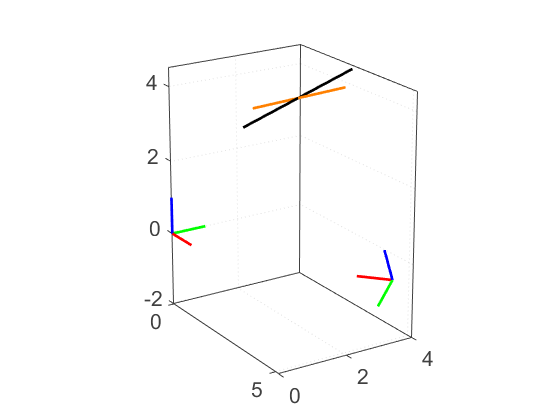

axes3 = axes('Parent',figure,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'ZColor',[0.25,0.25,0.25],...
    'Projection','perspective',...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes3,'on');
view(axes3,[57 20]);
hold(axes3,'all');

%Plot the world triad--------------------------------------
%Vectors for an world triad-----
w1 = [1,0,0]';
w2 = [0,1,0]';
w3 = [0,0,1]';

%Plot the triad-------
plot3([0;w1(1)],[0;w1(2)],[0;w1(3)],'Color',[1,0,0],'LineWidth',2)
plot3([0;w2(1)],[0;w2(2)],[0;w2(3)],'Color',[0,1,0],'LineWidth',2)
plot3([0;w3(1)],[0;w3(2)],[0;w3(3)],'Color',[0,0,1],'LineWidth',2)

%Camera triad----------------------------------------------
%Calculate the triad---
c1 = cAw *[w1; 1] ;
c2 = cAw * [w2;1];
c3 = cAw * [w3;1];

%Plot th cam triad-------
plot3([wc(1);c1(1)],[wc(2);c1(2)],[wc(3);c1(3)],'Color',[1,0,0],'LineWidth',2)
plot3([wc(1);c2(1)],[wc(2);c2(2)],[wc(3);c2(3)],'Color',[0,1,0],'LineWidth',2)
plot3([wc(1);c3(1)],[wc(2);c3(2)],[wc(3);c3(3)],'Color',[0,0,1],'LineWidth',2)

%Plot the segments in the world------------------------------
%Segment 1-----
plot3([A(1,2); A(1,1)] ,[A(2,2); A(2,1)],[A(3,2); A(3,1)],'Color',[1,0.5,0],'LineWidth',2)
%Segment 2-----
plot3([A(1,4); A(1,3)] ,[A(2,4); A(2,3)],[A(3,4); A(3,3)],'Color',[0,0,0],'LineWidth',2)


%Plot the camera plane------------------------------
%cA1 = cAw * [A(:,1);1];
%cA2 = cAw * [A(:,2);1];
%cA3 = cAw * [A(:,3);1];
%cA4 = cAw * [A(:,4);1];


%cpA1 = [cA1(1)/cA1(3) * f, cA1(2)/cA1(3) * f];
%cpA2 = [cA2(1)/cA2(3) * f, cA2(2)/cA2(3) * f] ;
%cpA3 = [cA3(1)/cA3(3) * f, cA3(2)/cA3(3) * f];
%cpA4 = [cA4(1)/cA4(3) * f, cA4(2)/cA4(3) * f] ;


%Segment 1-----
%plot([cpA2(1) - cpA1(1)],[cpA2(2) - cpA1(2)],'Color',[1,0.5,0],'LineWidth',2)
%Segment 2-----
%plot([cpA4(1) - cpA3(1)],[cpA4(2) - cpA3(2)],'Color',[0,0,0],'LineWidth',2)


## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame

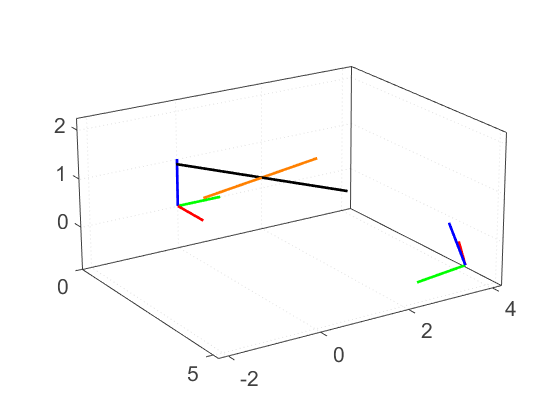

axes4 = axes('Parent',figure,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'ZColor',[0.25,0.25,0.25],...
    'Projection','perspective',...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes4,'on');
view(axes4,[57 20]);
hold(axes4,'all');

wAc = [cRw' wc; 0 0 0 1];

%Plot the camera triad--------------------------------------
%Vectors for an camera triad-----
c1 = [1,0,0]';
c2 = [0,1,0]';
c3 = [0,0,1]';

%Plot the triad-------
plot3([0;c1(1)],[0;c1(2)],[0;c1(3)],'Color',[1,0,0],'LineWidth',2)
plot3([0;c2(1)],[0;c2(2)],[0;c2(3)],'Color',[0,1,0],'LineWidth',2)
plot3([0;c3(1)],[0;c3(2)],[0;c3(3)],'Color',[0,0,1],'LineWidth',2)

%World triad----------------------------------------------
%Calculate the triad---
c1 = wAc *[w1; 1] ;
c2 = wAc * [w2;1];
c3 = wAc * [w3;1];

%Plot th cam triad-------
plot3([wc(1);c1(1)],[wc(2);c1(2)],[wc(3);c1(3)],'Color',[1,0,0],'LineWidth',2)
plot3([wc(1);c2(1)],[wc(2);c2(2)],[wc(3);c2(3)],'Color',[0,1,0],'LineWidth',2)
plot3([wc(1);c3(1)],[wc(2);c3(2)],[wc(3);c3(3)],'Color',[0,0,1],'LineWidth',2)
%Plot the segments in the camera------------------------------
%Segment 1-----
A2 = cAw * [A(:,2);1];
A1 = cAw * [A(:,1);1];

plot3([A2(1); A1(1)] ,[A2(2); A1(2)],[A2(3); A1(3)],'Color',[0,0,0],'LineWidth',2)

%Segment 2-----
A4 = cAw * [A(:,4);1];
A3 = cAw * [A(:,3);1];

plot3([A4(1); A3(1)] ,[A4(2); A3(2)],[A4(3); A3(3)],'Color',[1,0.5,0],'LineWidth',2)